# CIFAR-10 con red convolucional y una neurona selectiva

Ahora, vamos a añadir una neurona selectiva para tratar de mejorar los resultados de la red convolucional. Por simplificar, vamos a usar sólo dos clases: gato y coche, que tienen una amplia diferencia.

addpath(genpath('examples'));
SEED = 12345;
rng(SEED);

## Carga y normalización de los datos

[XTrain, YTrain, XTest, YTest] = ...
    loadCIFARData('examples/data/cifar-10');

cats = YTrain == 'cat';
cars = YTrain == 'automobile';
indices = cats | cars;

XTrain = cast(XTrain(:, :, :, indices), 'double') / 255;
YTrain = YTrain(indices);

cats = YTest == 'cat';
cars = YTest == 'automobile';
indices = cats | cars;

YTest = YTest(indices);
XTest = cast(XTest(:, :, :, indices), 'double') / 255;

YTrain = removecats(YTrain);
YTest = removecats(YTest);

## Subivisión de los conjuntos

El de entrenamiento se va a subdividir en validación y el de test en entrenamiento y test para la neurona selectiva.

[trainInd, valInd, ~] = dividerand(length(XTrain), .9, .1, .0);

XVal = XTrain(:, :, :, valInd);
YVal = YTrain(valInd);

XTrain = XTrain(:, :, :, trainInd);
YTrain = YTrain(trainInd);

## Creación de la red

Esta vez debe ser mucho más simple.

layers = [
    imageInputLayer([32 32 3], 'Name', 'input')
    
    convolution2dLayer([3 3], 32, 'Name', 'conv')
    reluLayer('Name', 'relu')
    maxPooling2dLayer([2 2], 'Stride', [2 2], 'Name', 'max-pooling')
    
    fullyConnectedLayer(2, 'Name', 'head')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

## Opciones de entrenamiento

miniBatchSize = 16;

options = trainingOptions('sgdm', ...
    'MiniBatchSize', miniBatchSize, ...
    'MaxEpochs', 20, ...
    'InitialLearnRate', .001, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XVal, YVal}, ...
    'ValidationFrequency', miniBatchSize * 8, ...
    'Verbose', false, ...
    'Plots', 'training-progress' ...
);

## Entrenamiento

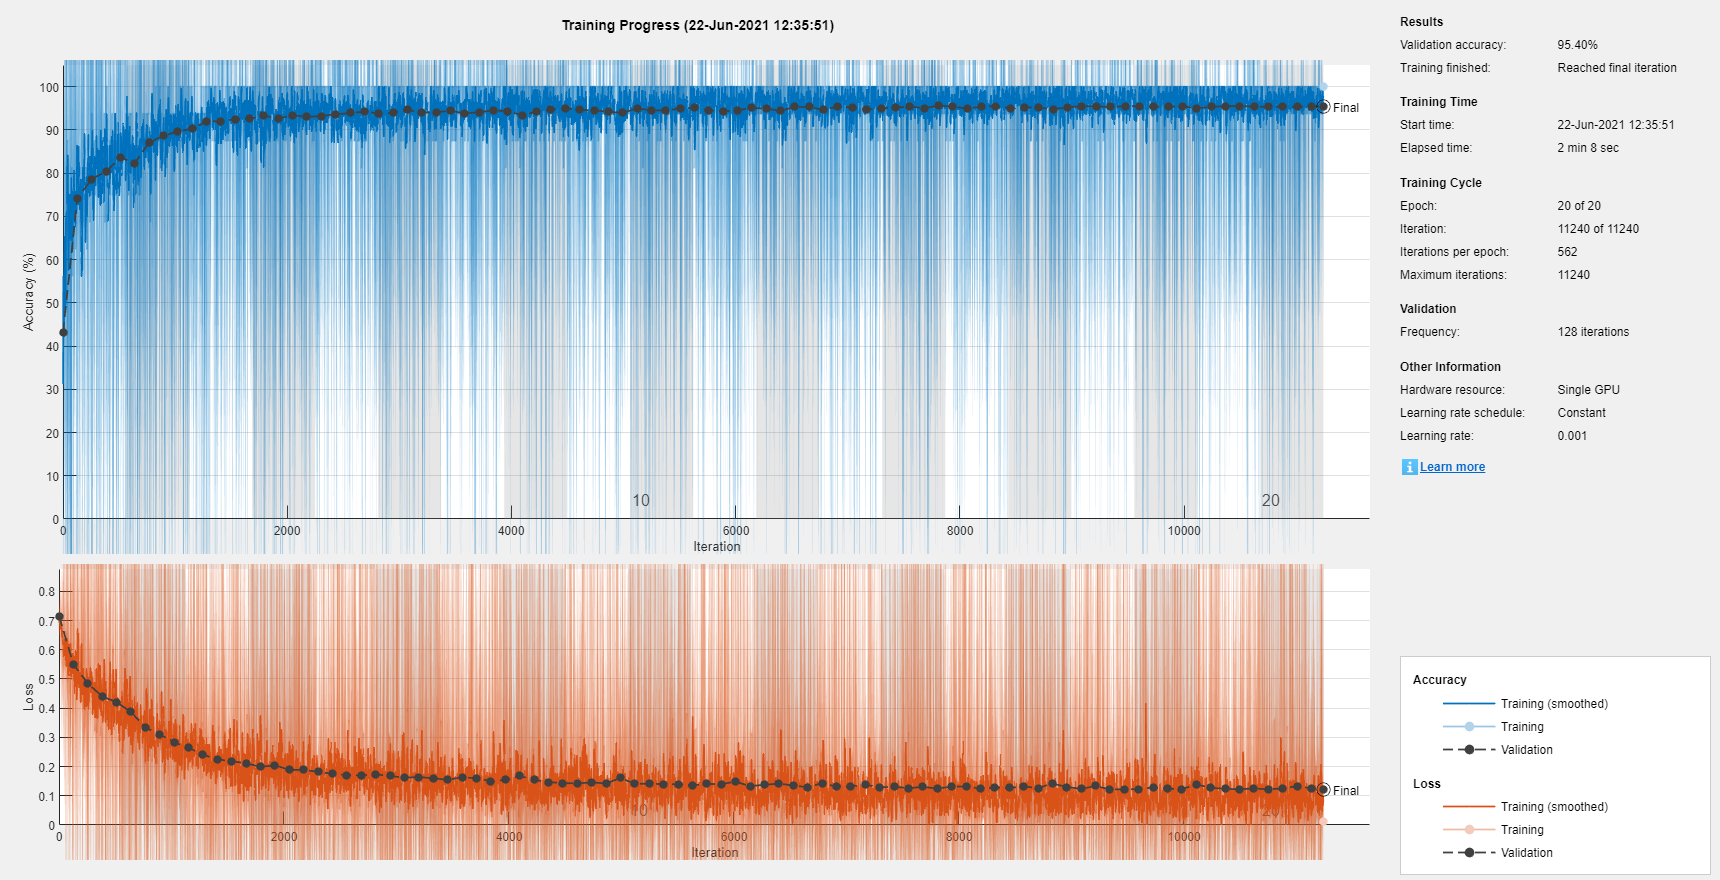

[net, info] = trainNetwork(XTrain, YTrain, layers, options);

save('examples/models/cifar10SelCats.mat', 'net');
save('examples/models/cifar10SelCatsInfo.mat', 'info');

net = load('examples/models/cifar10SelCats.mat').net;

## Evaluación

cs = net.Layers(end).Classes;

probs = predict(net, XTest);
[~, YPred] = max(probs, [], 2);
YPred = cs(YPred);
acc = sum(YPred == YTest) / length(YTest);

fprintf("****************\n");

****************


fprintf("Accuracy: %0.4f\n", acc);

Accuracy: 0.9535


fprintf("****************\n");

****************


## Resultados

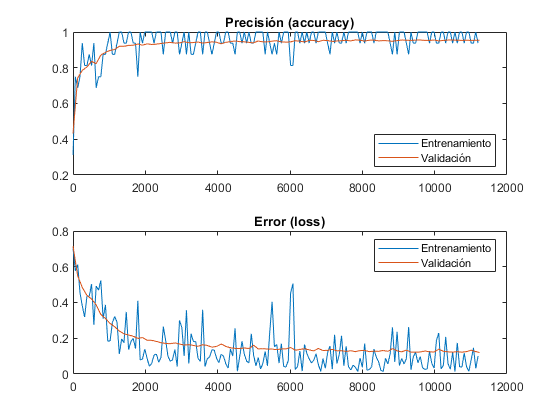

plotTraining(info, miniBatchSize * 4);

## Segundo dataset

Cargamos el dataset con los ejemplos de los tres gatos concretos. Comprobamos, además, que la red los clasifique como tal.

%catImgsStore = imageDatastore('examples/data/cats', ...
%    'IncludeSubfolders', true, 'LabelSource', 'foldernames');
catImgsStore = imageDatastore('examples/data/cats');
nFiles = length(catImgsStore.Files);
catImgs = zeros(32, 32, 3, nFiles);
%catLabels = catImgsStore.Labels;
for i = 1:nFiles
    catImgs(:, :, :, i) = cast(imread(catImgsStore.Files{i}), 'double') / 255;
end

probs = predict(net, catImgs);
disp(cs.');

     automobile      cat 



disp(probs);

    0.0015    0.9985
    0.0008    0.9992
    0.0020    0.9980
    0.0069    0.9931
    0.0004    0.9996



## Neurona selectiva

Vamos a ver si la neurona selectiva es capaz de reconocer las imágenes de un solo gato, pero no del resto.

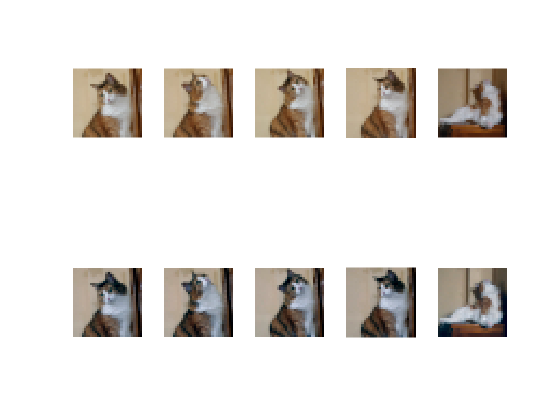

stdCatImgs = standarize(XTrain, catImgs);

nExamples = size(stdCatImgs, 4);
figure;
for i = 1:nExamples
    subplot(2, 2 * nExamples / 2, i);
    imshow(catImgs(:, :, :, i));
    subplot(2, 2 * nExamples / 2, i + nExamples);
    imshow(stdCatImgs(:, :, :, i));
end

selectedIdx = 1:5;
XSel = toSelectiveInput(net, stdCatImgs);
XSel = l2(XSel);
XTrainSel = XSel(:, selectedIdx);

% Elegimos los predichos como gatos
XTestSel = toSelectiveInput(net, XTest(:, :, :, YPred == 'cat'));
XTestSel = l2(XTestSel);

XMean = mean(XTrainSel, 2);
w = XMean / norm(XMean);
epsilon = .01;
theta = min(w.' * XTrainSel) - epsilon;

fprintf("Activated for selected cat: %s\n", ...
    mat2str(w.' * XTrainSel - theta > 0));

Activated for selected cat: [true true true true true]


fprintf("Activations for cat examples: %d\n", ...
    sum(w.' * XSel - theta > 0));

Activations for cat examples: 5


fprintf("Activations for cat-classified examples: %d/%d\n", ...
    sum(w.' * XTestSel - theta > 0), sum(YPred == 'cat'));

Activations for cat-classified examples: 0/997


function y = standarize(X, x)
    mu = mean(X, [1, 2]);
    mu = mean(mu, 4);
    sigma = std(X, [], [1, 2]);
    sigma = mean(sigma, 4);
    mu_ = mean(x, [1, 2]);
    sigma_ = std(x, [], [1, 2]);
    y = min(1, max(0, ((x - mu_)./ sigma_).* sigma + mu));
end

function Y = toSelectiveInput(net, X)
    Z1 = activations(net, X, 'max-pooling', 'OutputAs', 'columns');
    Z2 = activations(net, X, 'head', 'OutputAs', 'columns');
    Y = [Z1; Z2];
end

function y = l2(x)
    y = x./ vecnorm(x, 2);
end